# Brain Imaging Data Structure (BIDS)

Testing MATLAB BIDS implementaion for working remotely with data from [Open](http://openneuro.org) [Neuro](http://openneuro.org) platform. 

bucket = "openneuro.org";

## Initial S3 Loading of Data

This step requires specifying the Amazon "bucket" - a public cloud storage resource that is available in [Amazon Web Services (AWS)](https://aws.amazon.com/). Data is stored inside these S3 buckets into distinct folders.

Here, we specify our bucket and folder location:

ID = "ds004489";  %  Example used: MRI (https://openneuro.org/datasets/ds004489/versions/1.0.0)
modality = "MRI";

We can then initialize our BIDS object, which will return a MATLAB [table](https://www.mathworks.com/help/matlab/tables.html) showing what is inside our study of choice.

dataset = BIDS(bucket, ID, modality);

disp(dataset)

  BIDS with properties:

     participants: [15×8 table]
         BIDSData: {3×1 cell}
    about_dataset: [1×1 struct]
             info: [1×1 struct]
     folder_files: [1×1 struct]
         encoding: [1×1 struct]



## Viewing BIDS Object Properties 

dataset is now a BIDS object with its standard properties listed as follows:

                    ***.encoding****             - struct     - data encoding information*

                    *.****about_dataset****     - struct     -  dataset_description.json*

                    ***.participants    ****     -  table     -  data table*

                    ***.BIDSData****             -   cell       -  file data location*

                    ***.info****                       - struct     -  participants.json*

                    ***.folder_files****          - struct     -  complete folder structure of S3 folder*

BIDS properties can also be viewed by dot indexing. Property will be empty if particular file was not found.

disp(dataset.about_dataset)

                Name: 'Raw data for Engaging in word recognition elicits highly specific modulations in visual cortex'
             Authors: {4×1 cell}
    HowToAcknowledge: 'Please cite this paper: Engaging in word recognition elicits highly specific modulations in visual cortex, published in Current Biology, 2023'
             Funding: {5×1 cell}
         BIDSVersion: '1.8.0'
         DatasetType: 'raw'
             License: 'CC0'
          DatasetDOI: 'doi:10.18112/openneuro.ds004489.v1.0.0'



disp(dataset.encoding)

    modality_properties: dictionary (string ⟼ cell) with 2 entries
               modality: "mri"
                 bucket: "openneuro.org/"
                     ID: "ds004489/"
                    dir: "s3://openneuro.org/ds004489/"



## Viewing and Selecting from Participants Field

For viewing MATLAB [table](https://www.mathworks.com/help/matlab/tables.html) elements, such as the **participants** property of our BIDS Object,  [table indexing](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) is possible to select specific participants. This field will only be populated if file 'participants.tsv' is in the root bucket/ID foder.

dataset.participants

ans = 15×8 table
    participant_id    age      gender      handedness    handednessScore    twre_index    twre_pde_ss    twre_swe_ss
    ______________    ___    __________    __________    _______________    __________    ___________    ___________

     {'sub-114' }     24     {'male'  }    {'right'}            20              114          113.5          112.5   
     {'sub-136' }     25     {'female'}    {'left' }           0.5            117.5          112.5            121   
     {'sub-505' }     22     {'female'}    {'right'}            19            123.5            114            130   
     {'sub-562' }     26     {'male'  }    {'right'}            18              126          122.5            127   
     {'s

[male_rows, ~] = find(strcmp(dataset.participants.gender, 'male'));
male_table = dataset.participants(male_rows, :)

male_table = 5×8 table
    participant_id    age     gender     handedness    handednessScore    twre_index    twre_pde_ss    twre_swe_ss
    ______________    ___    ________    __________    _______________    __________    ___________    ___________

     {'sub-114'}      24     {'male'}    {'right'}           20               114          113.5          112.5   
     {'sub-562'}      26     {'male'}    {'right'}           18               126          122.5            127   
     {'sub-736'}      28     {'male'}    {'right'}           20               124            119            130   
     {'sub-821'}      21     {'male'}    {'right'}           19               129          126.5          128.5   
     {'sub-835

Note: If there is interest in loading participant files that is not within the root folder, such as in Derivatives folders, search within the **folder_files** property for the particular folder.

dataset.folder_files.folders

ans = 16×2 table
         name                      folder             
    _______________    _______________________________

    {'derivatives'}    {'s3://openneuro.org/ds004489'}
    {'sub-1014'   }    {'s3://openneuro.org/ds004489'}
    {'sub-114'    }    {'s3://openneuro.org/ds004489'}
    {'sub-136'    }    {'s3://openneuro.org/ds004489'}
    {'sub-505'    }    {'s3://openneuro.org/ds004489'}
    {'sub-562'    }    {'s3://openneuro.org/ds004489'}
    {'sub-582'    }    {'s3://openneuro.org/ds004489'}
    {'sub-585'    }    {'s3://openneuro.org/ds004489'}
    {'sub-628'    }    {'s3://openneuro.org/ds004489'}
    {'sub-667'    }    {'s3://openneuro.org/ds004489'}
    {'sub-701'    }    {'s3://openneuro.org/ds004489'}
    {'sub-728'    }    {'s3://openneuro.org/ds004489'}
    {'sub-731'    }    {'s3://openneuro.org/ds004489'}
    {'sub-736'    }    {'s3://openneuro.org/ds004489'}
    {'sub-821'    }    {'s3://open

Here, we see that there exists a Derivative folder in this dataset, and can be accessed once again by dot indexing to view the folders or files.

derivatives_info = dataset.folder_files.substructures{1}

derivatives_info = struct with fields:
             name: 's3://openneuro.org/ds004489/derivatives'
            files: [1×2 table]
          folders: [14×2 table]
    substructures: {14×14 cell}


derivatives_info.folders

ans = 14×2 table
         name                           folder                   
    ______________    ___________________________________________

    {'sourcedata'}    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-114'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-136'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-505'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-562'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-582'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-585'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-628'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-667'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-701'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-728'   }    {'s3://openneuro.org/ds004489/derivatives'}
    {'sub-731'   }    {'s3://openneuro.org/ds004489/deri

## Understanding BIDSDataStore Objects

The field 'BIDSData' contains objects that hold information about the dataset. These objects are BIDSDataStores, and they each constitute for a given extension found within the specified bucker and ID.

disp(dataset.BIDSData)

    {1×1 BIDSDataStore}
    {1×1 BIDSDataStore}
    {1×1 BIDSDataStore}



As shown, there are three distinct BIDSDataStores that were created by default from the initial load. To access more informatoin about each one, index into the cell to view its contents.

dataset.BIDSData{:}

ans =   BIDSDataStore with properties:

    extension: ".json"
     modality: "mri"
        files: [2174×2 table]


ans =   BIDSDataStore with properties:

    extension: ".gz"
     modality: "mri"
        files: [2506×2 table]


ans =   BIDSDataStore with properties:

    extension: ".tsv"
     modality: "mri"
        files: [504×2 table]


Each of the BIDSDataStore Object contains an extension, modality, and a table with all of the files found with given extension in the entire bucket/ID. To view the files within the **files** property of a BIDSDatastore object, we can select and show using dot indexing once again:

my_data = dataset.BIDSData{3};      % selecting BIDSDataStore with .tsv extension with 504 files
disp(my_data.files)

                                                               FileName                                                                FileSize 
    ______________________________________________________________________________________________________________________________    __________

    "s3://openneuro.org/ds004489/participants.tsv"                                                                                           710
    "s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-Retinotopy_run-1_desc-confounds_timeseries.tsv"    1.0367e+06
    "s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-Retinotopy_run-2_desc-confounds_timeseries.tsv"    1.0072e+06
    "s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-Retinotopy_run-3_desc-confounds_timeseries.tsv"    9.8854e+05
    "s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/fu

## Selecting and Reading BIDSDataStore Data

To read a selection of the files within a BIDSDataStore object, there are multiple options:

- **TABLE: **Create a table with desired fields to filter (i.e. 'partipant_id' or 'sub_id')

- **NUMERIC: **As an integer or an array, index from the BIDSDataStore which files you'd like to load.

- **STRING (Coming Soon) : **Load by folder/file filter created by the input string.

In this demonstration, the participant table will be used to load desired subject data.

disp(male_table)

    participant_id    age     gender     handedness    handednessScore    twre_index    twre_pde_ss    twre_swe_ss
    ______________    ___    ________    __________    _______________    __________    ___________    ___________

     {'sub-114'}      24     {'male'}    {'right'}           20               114          113.5          112.5   
     {'sub-562'}      26     {'male'}    {'right'}           18               126          122.5            127   
     {'sub-736'}      28     {'male'}    {'right'}           20               124            119            130   
     {'sub-821'}      21     {'male'}    {'right'}           19               129          126.5          128.5   
     {'sub-835'}      19     {'male'}

data = my_data.read(male_table);

Reading from MRI BIDSDataStore with extension(s): .tsv
Specification: Table
Reading 147 files from BIDSDataStore...
Load Complete!


In this load, only those files that contained given participant_id specification were loaded. 

data

data = 147×2 cell array
    {253×267 table}    {'s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-Retinotopy_run-1_desc-confounds_timeseries.tsv'}
    {253×259 table}    {'s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-Retinotopy_run-2_desc-confounds_timeseries.tsv'}
    {253×256 table}    {'s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-Retinotopy_run-3_desc-confounds_timeseries.tsv'}
    {275×275 table}    {'s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-catLoc_run-1_desc-confounds_timeseries.tsv'    }
    {275×270 table}    {'s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-catLoc_run-2_desc-confounds_timeseries.tsv'    }
    {275×262 table}    {'s3://openneuro.org/ds004489/derivatives/sub-114/ses-1/func/sub-114_ses-1_task-catLoc_run-3_desc-confounds_timeseries.tsv'    }
    {275×271 table}    {'s3://openneuro.org/ds004489/derivatives

Lastly, one can easily access loaded data using cell indexing to extract the data given. By default the data was loaded as tables because these files were of '.tsv' extension. Of course, any desired form of plotting can be used to visualize the data.

data{1}

ans = 253×267 table
    global_signal    global_signal_derivative1    global_signal_derivative1_power2    global_signal_power2     csf      csf_derivative1    csf_derivative1_power2    csf_power2    white_matter    white_matter_derivative1    white_matter_power2    white_matter_derivative1_power2    csf_wm    tcompcor    std_dvars    dvars     framewise_displacement      rmsd      t_comp_cor_00    t_comp_cor_01    t_comp_cor_02    t_comp_cor_03    t_comp_cor_04    t_comp_cor_05    t_comp_cor_06    a_comp_cor_00    a_comp_cor_01    

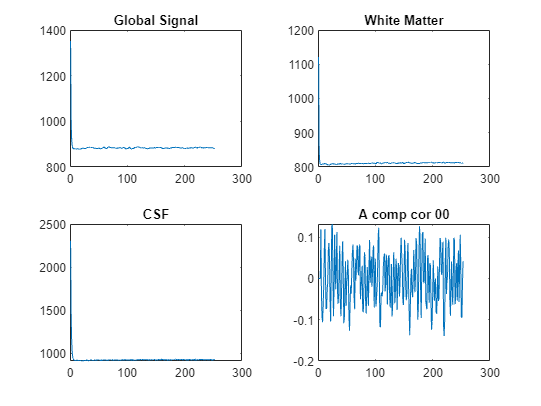

tiledlayout(2,2)

% Tile 1
nexttile
plot(data{1}.global_signal)
title('Global Signal')
% Tile 2
nexttile
plot(data{1}.white_matter)
title('White Matter')
% Tile 3
nexttile
plot(data{1}.csf)
title('CSF')
% Tile 4
nexttile
plot(data{1}.a_comp_cor_00)
title('A comp cor 00')